# **Task_02:**  Explore a 3 Floor Tower with **MOVING** Ground 

Let's explore a 3 Floor tower with **a MOVING ground** ... specifically we'll define a **GROUND motion profile **that moves at the **same frequency as a RESONANCE of the ORIGINAL building** (hey ... what could go wrong ?)

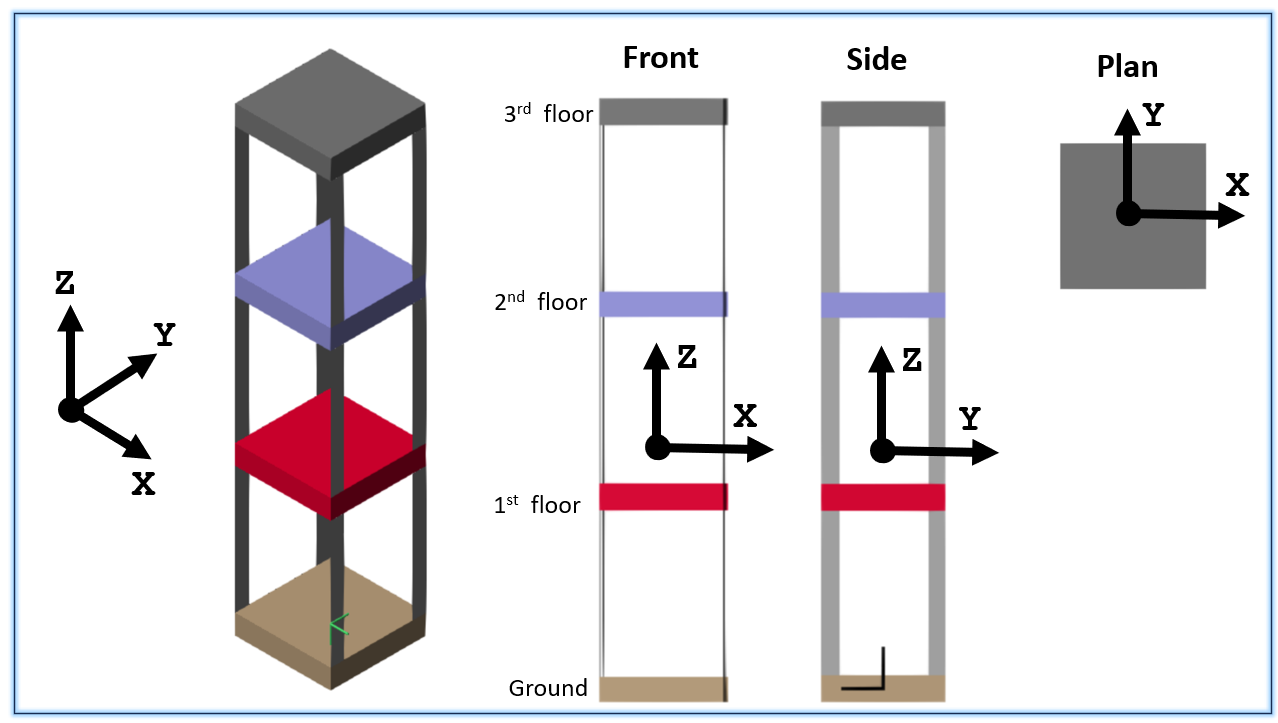

## Clear the workspace

clear

## Consult Parameter database

params_dB = bh_flex_tower_params_CLS("bh_flex_tower_params_database.xlsx", "DEFAULT");

## Define the columns

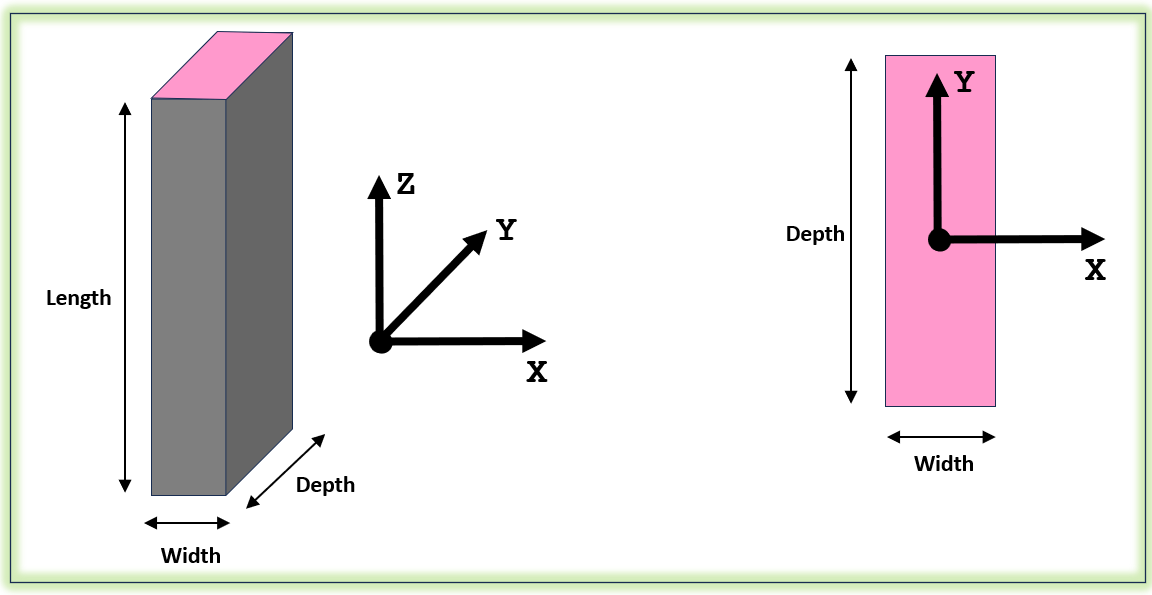

col_OBJ  = bh_create_column_OBJ( Width=params_dB.col_width_x, ...
                                 Depth=params_dB.col_depth_y, ...
                                 Length=params_dB.col_length_z, ...
                                 density=params_dB.col_density, ...
                                 E_GPa_Young=params_dB.col_E_Gpa, ...
                                 v_Poisson=params_dB.col_Poisson);

col_OBJ.num_eles      = params_dB.col_num_eles;

Define column damping

col_OBJ.damp_ratio = params_dB.col_damp_ratio;

So what've we got

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 3.5000e-04
          DEPTH_y: 0.0170
         LENGTH_z: 0.1600
          density: 7900
      E_GPa_Young: 170
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 1.0000e-03
       damp_ratio: 0.0500
         num_eles: 1
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0075
              vol: 9.5200e-07
               Ix: 1.4330e-10
               Iy: 6.0740e-14
               Kx: 30.2512
             area: 5.9500e-06


## Define the floors

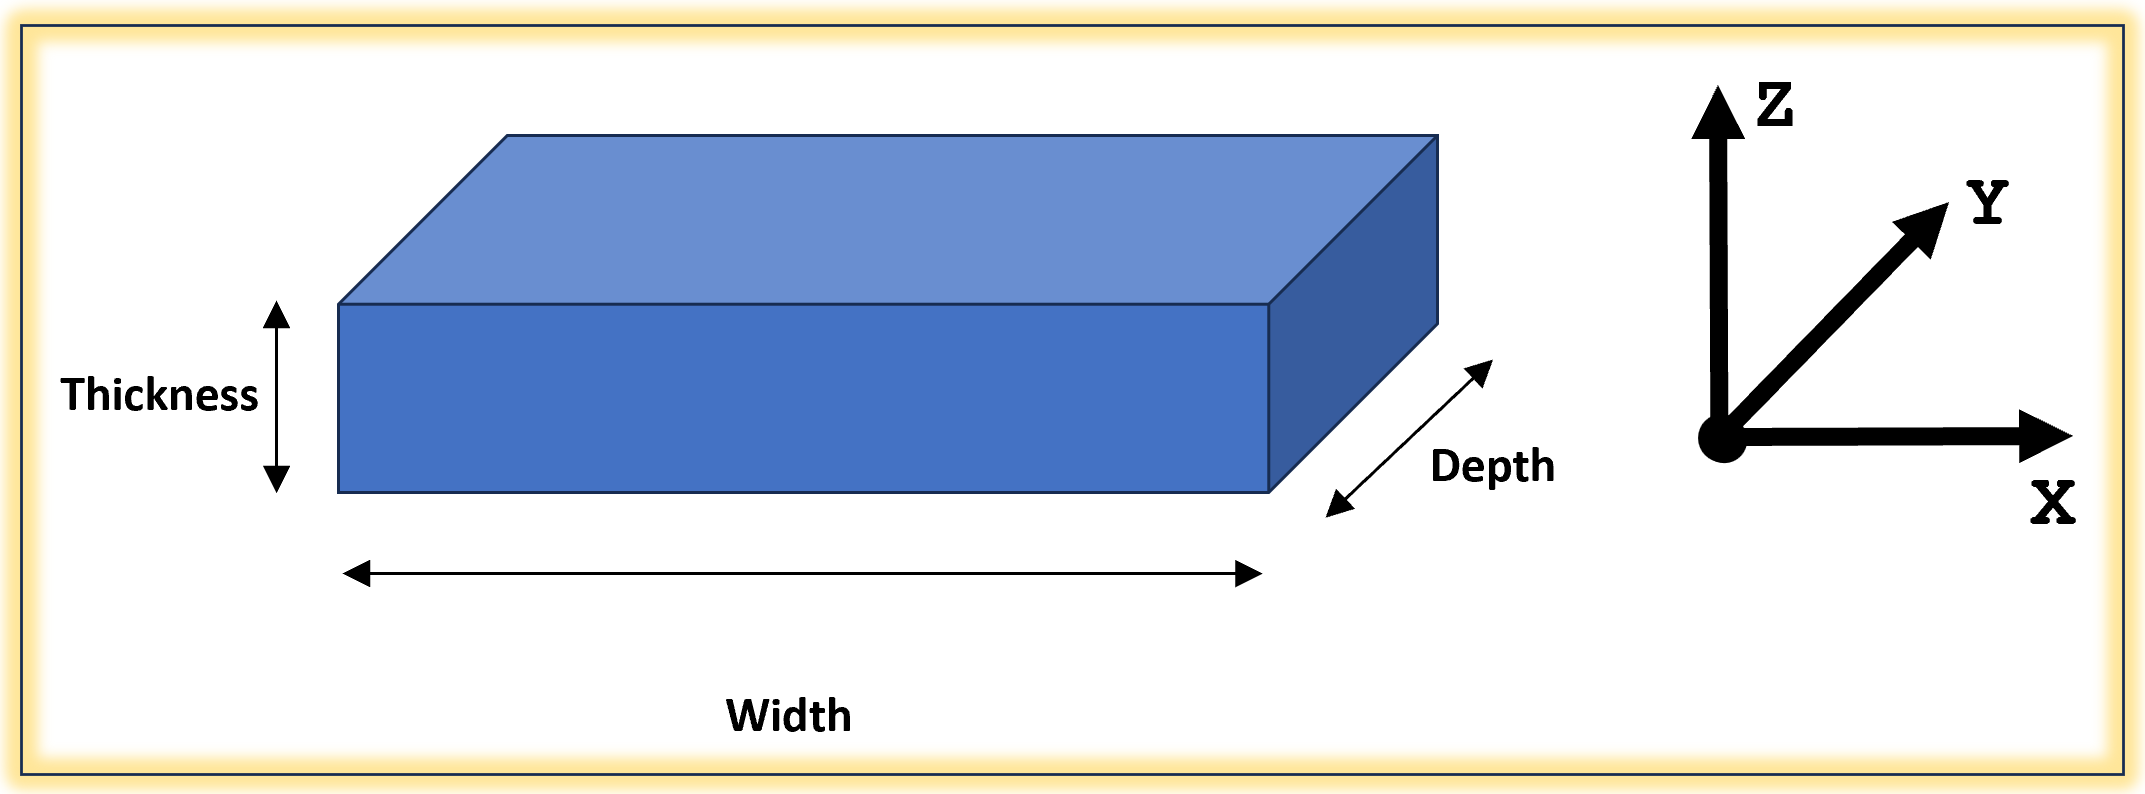

floor_OBJ = bh_create_floor_OBJ( Width=params_dB.floor_width_x, ...
                                 Depth=params_dB.floor_depth_y, ...
                                 Thickness=params_dB.floor_thick_z, ...
                                 Mass=params_dB.floor_mass )

floor_OBJ =   bh_solid_floor_CLS with properties:

        WIDTH: 0.1200
        DEPTH: 0.1200
    THICKNESS: 0.0250
         MASS: 0.5080


**Define baseline resonances:**

Recall from [`TASK_01b_3floor_tower_do_sys_ID.mlx`](matlab:  open  TASK_01b_3floor_tower_do_sys_ID.mlx) we extracted the natural frequencies of the **original** building and saved them to a MAT file **bh_SYS_ID_RESULTS.mat**

- 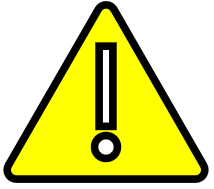 NOTE that the "CONFIRMED" version of the file was manually created

%whos("-file", "bh_SYS_ID_RESULTS.mat")
tmp_S            = load("bh_SYS_ID_RESULTS_CONFIRMED.mat")

tmp_S = struct with fields:
    wn_radpersec_original_building: [3×1 double]


w_baseline_list  = tmp_S.wn_radpersec_original_building % (rad/s)

w_baseline_list =     6.7277
   18.8706
   27.3085


w2_baseline_list = w_baseline_list.^2;

## Define parameters for the checkered looking Earth ground

earth_vis_OBJ = earth_vis_CLS();
earth_vis_OBJ.tile_L = 0.1;  % (m)

## Open and RUN the Simulink model

When you open this model, select which structural resonance you want to excite:

- Opening the **Model Browser**

- Click on the **GROUND_MOTION** Subsystem

- Interact with the **YELLOW dropbox** and choose which resonance to run (e.g.:  $\left.1^{\mathrm{st}} \;,2^{\mathrm{nd}} ,3^{\mathrm{rd}\;} \right)$

- NOTE:  index choices $4^{\mathrm{th}} ,5^{\mathrm{th}} ,6^{\mathrm{th}}$ allow other excitation frequencies to be applied

- Run the Simulation and observe the structure's response

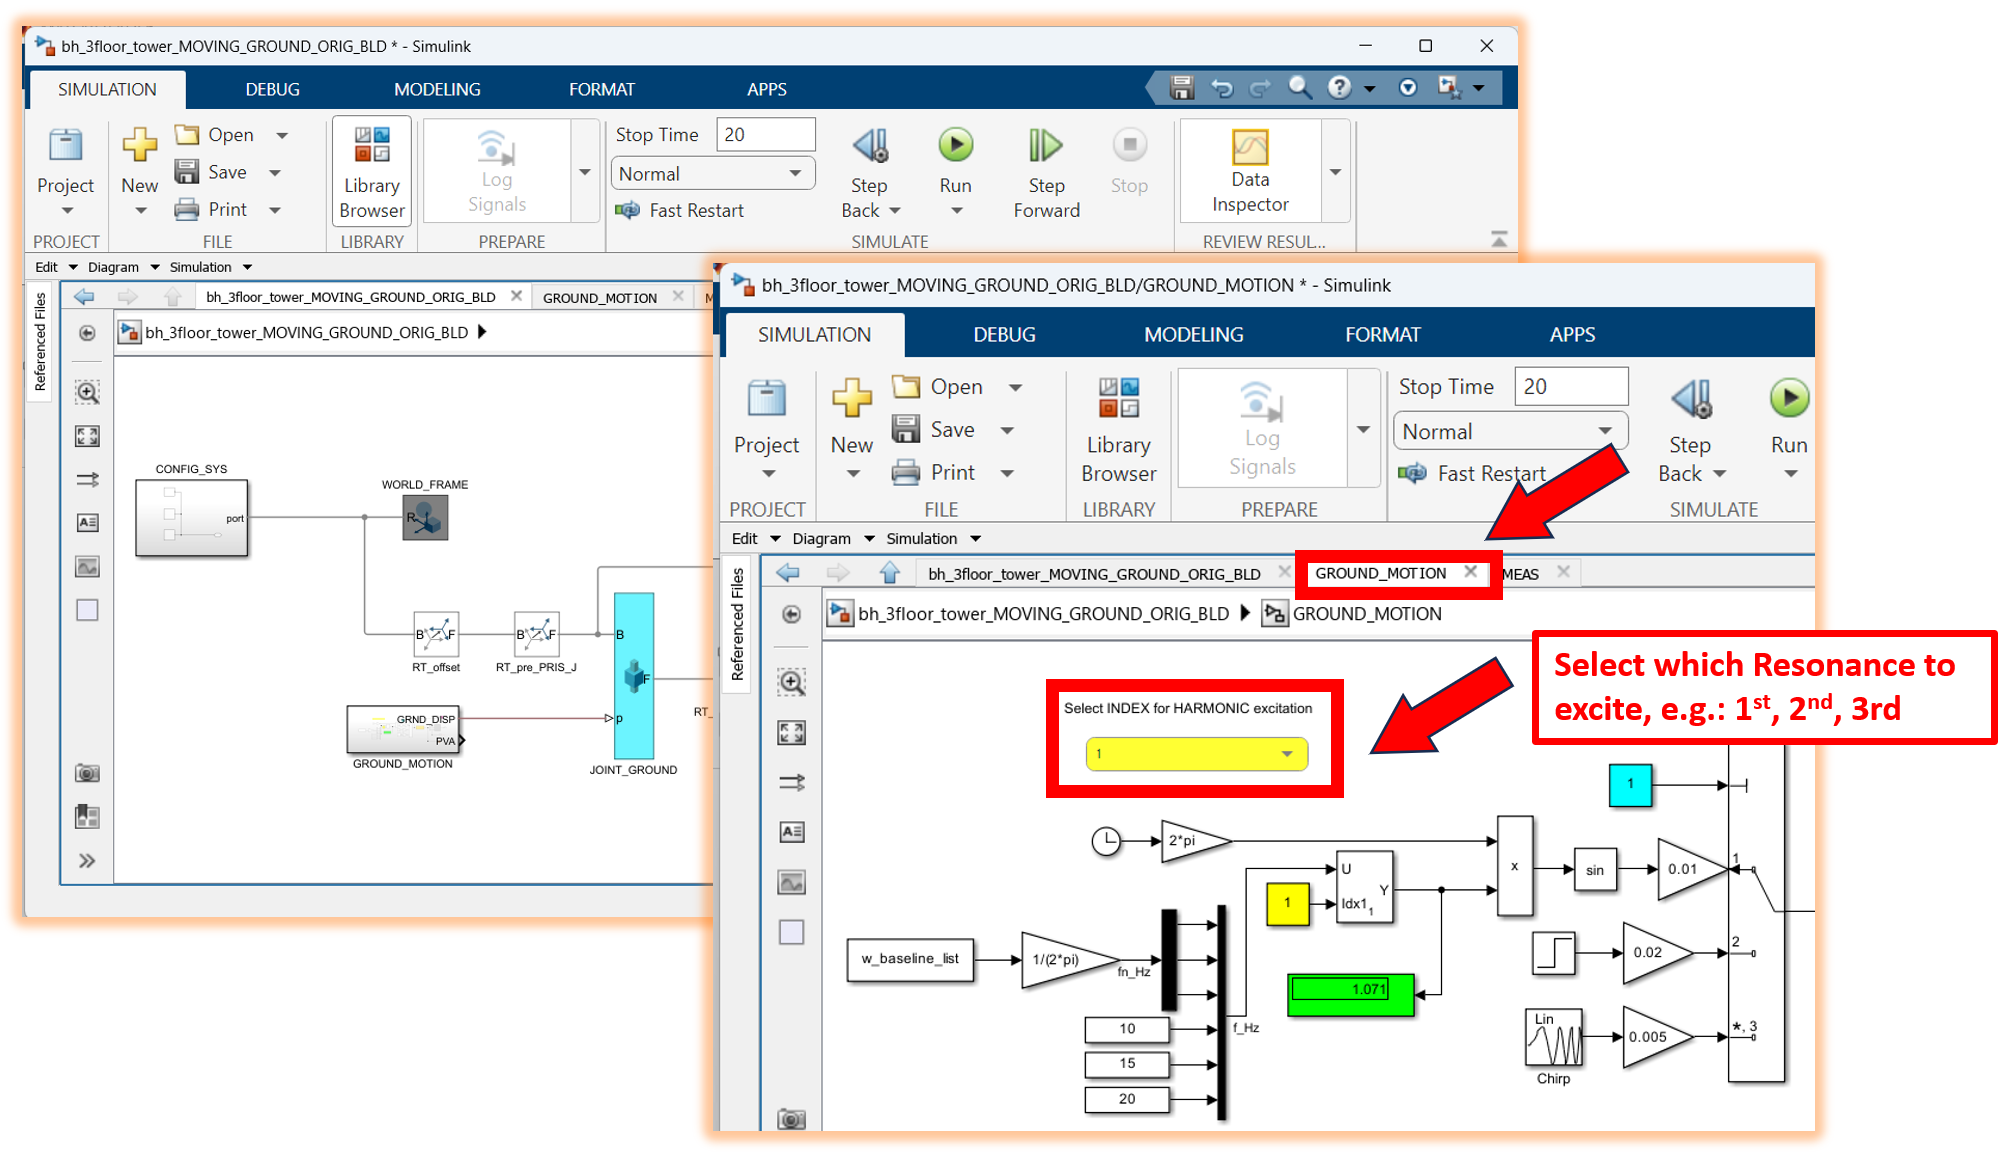

 As the structure responds to the ground excitation .... can you "see" the mode shape corresponding to the resonance that you're exciting the system at ?

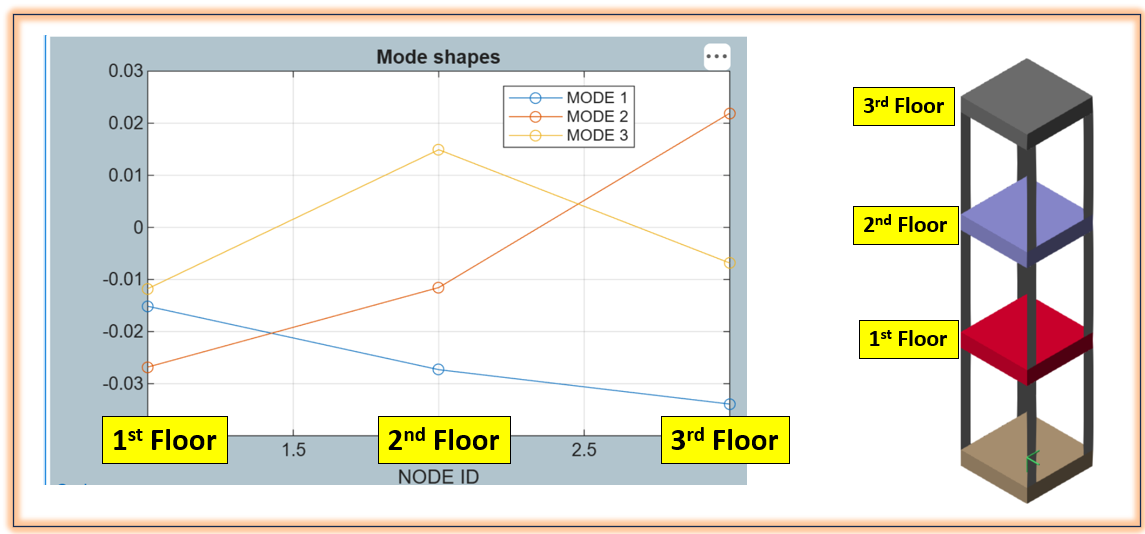

open_system("bh_3floor_tower_MOVING_GROUND_ORIG_BLD")